% Works to produce an output .AVI video flashing at 40Hz for 40Hz
% stimulation.
% Created on 04-01-2020 by Pho Hale.

## Settings:

% General
videoResolutionSize = 64; % 64 x 64
% Want it to flash 40 times a second.

fs = 120; % Samples per second

totalDurationSeconds = 1; % Specified in seconds.
t = 0:1/fs:totalDurationSeconds;

## Build the square wave outputs:

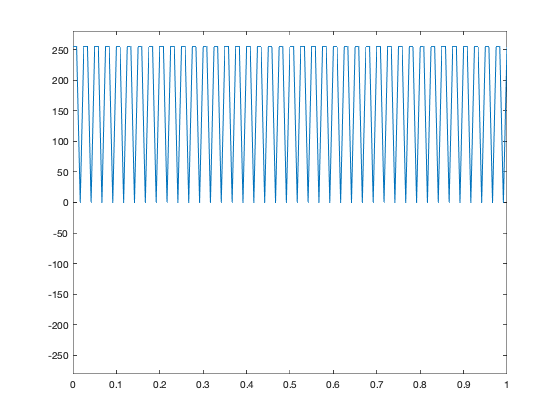

freq=40;
offset=0;
amp=double(intmax('uint8'));
duty=50;
%t=0:0.01:100;%100 seconds
sq_wav=offset+amp*square(2*pi*freq.*t,duty);
sq_wav(sq_wav < 0) = 0;
sq_wav = uint8(sq_wav);
plot(t,sq_wav)
ylim([-amp*1.1, amp*1.1])

## Create the data:

video_file_path = 'output/40hz_video.avi';
v = VideoWriter(video_file_path,'Grayscale AVI');
open(v)
for i = 1:length(t)
    curr_elem = sq_wav(i);
    curr_frame = repelem(curr_elem, videoResolutionSize, videoResolutionSize);
    writeVideo(v,curr_frame);
end
close(v)



% Write the frames:
